clc; clear; close all; 
addpath('functions/');

n = 200;
x1 = 5;
v1 = 1;
t = 1;
sigmaA = 0.2;
sigmaN = 20;

G = [(t^2)/2; t];
F = [1, t; 0, 1];
H = [1, 0];

% [ X, Z, a, Noise ] = randomAcceleration( n, sigmaA, sigmaN, x1, v1, t); 
% [ X, Z, a, Noise ] = rndAccStateSpace( n, sigmaA, sigmaN, x1, v1, t, F, G, H); 

a = normrnd(0,sigmaA,1,n);
Noise = normrnd(0,sigmaN,1,n);

G = [(t^2)/2; t];
F = [1, t; 0, 1];
H = [1, 0];

X = zeros(2, n);
Z = zeros(1, n);
X(:, 1) = [x1; v1];

for i=2:n
    X(:, i) = F*X(:,i-1) + G*a(i);
    Z(i) = H*X(:,i) + Noise(i); 
end

Xk = zeros(2, n);
Xk(:, 1) = [x1; v1];

Q=sigmaA^2 * (G*G');
P=[10000, 0; 0, 10000];

for i=2:n
    P=F*P*F'+Q;
    K=P*H'/(H*P*H'+ sigmaN^2);
    Xk(:,i) = F*Xk(:, i-1);
    Xk(:,i) = Xk(:,i)+K*(Z(i)-H*Xk(:,i));
    
    P=(eye(2)-K*H)*P;
end

K =     0.9804
    0.4902


K =     0.9363
    0.8427


K =     0.8082
    0.4670


K =     0.6872
    0.2884


K =     0.5924
    0.1947


K =     0.5188
    0.1401


K =     0.4608
    0.1056


K =     0.4142
    0.0824


K =     0.3760
    0.0662


K =     0.3443
    0.0544


K =     0.3175
    0.0455


K =     0.2947
    0.0387


K =     0.2751
    0.0334


K =     0.2580
    0.0292


K =     0.2431
    0.0258


K =     0.2300
    0.0230


K =     0.2184
    0.0207


K =     0.2082
    0.0188


K =     0.1990
    0.0172


K =     0.1909
    0.0159


K =     0.1837
    0.0148


K =     0.1772
    0.0139


K =     0.1714
    0.0131


K =     0.1663
    0.0124


K =     0.1617
    0.0119


K =     0.1576
    0.0114


K =     0.1540
    0.0110


K =     0.1508
    0.0107


K =     0.1479
    0.0104


K =     0.1455
    0.0102


K =     0.1433
    0.0100


K =     0.1414
    0.0098


K =     0.1398
    0.0097


K =     0.1384
    0.0096


K =     0.1372
    0.0095


K =     0.1362
    0.0095


K =     0.1353
    0.0094


K =     0.1346
    0.0094


K =     0.1341
    0.0094


K =     0.1336
    0.0093


K =     0.1332
    0.0093


K =     0.1329
    0.0093


K =     0.1326
    0.0093


K =     0.1324
    0.0093


K =     0.1323
    0.0093


K =     0.1322
    0.0093


K =     0.1321
    0.0093


K =     0.1320
    0.0093


K =     0.1320
    0.0093


K =     0.1320
    0.0093


K =     0.1320
    0.0093


K =     0.1320
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


K =     0.1319
    0.0093


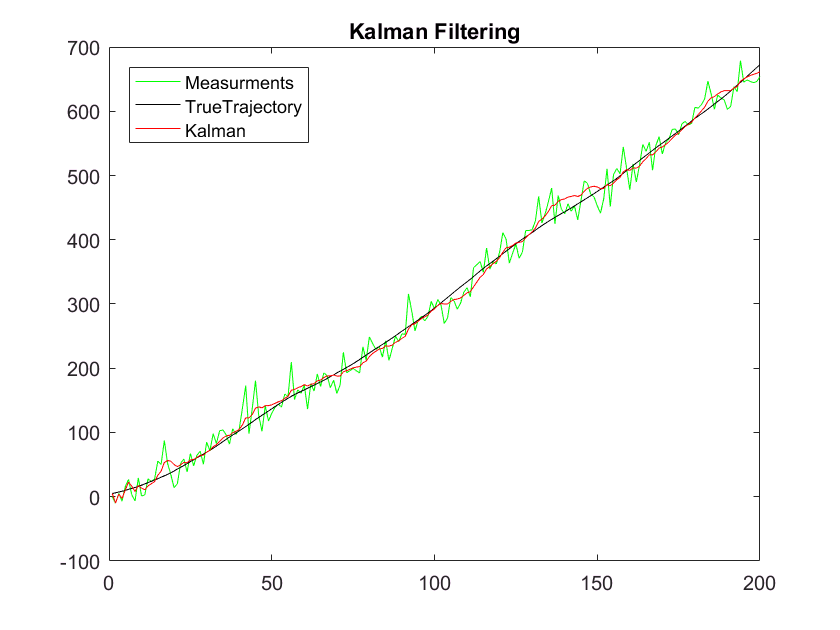


% figure;
plot (Z,'green')
hold on;
plot (X(1,:),'black');
plot (Xk(1,:),'red');
legend('Measurments','TrueTrajectory','Kalman','Location','northwest');
title('Kalman Filtering');